addpath('lib')
addpath('lib\funzioni')  
addpath('lib\Sottoclassi_di_Distributions') 

Bello Renato - 341965, Chiodo Martina - 343310

# **HOMEWORK BA**

## **Introduzione**

Per questo homework abbiamo sviluppato una semplice libreria per la simulazione di un processo modellabile tramite una **Rete di Jackson**, composta da un insieme di code e server. I principali oggetti della libreria sono:

- **Network**: rappresenta l’intera rete in cui si svolge la simulazione. È composta da un insieme di nodi collegati tra loro secondo quanto specificato da una **matrice di adiacenza**, che definisce le probabilità di transizione tra i nodi. si noti che la matrice di adiacenza è  da definire in modo tale che esista un **nodo sink**, ossia un nodo attrattore raggiungibile da qualsiasi altro nodo della rete e da cui non è possibile uscire.

- **Nodo**: è l'elemento base della rete. Ogni nodo è costituita da una **coda**, che può essere gestita con politica *FIFO* o *LIFO*, da un **insieme di server**, ciascuno caratterizzato da una sua distribuzione di tempi di servizio, e da una **distribuzione degli interarrivi** per modellare l'arrivo di entità esterne alla rete.

- **Evento**: rappresenta il meccanismo che fa progredire la simulazione, ad ogni evento corrisponde un'azione specifica che modifica lo stato del sistema. Nella libreria, questo concetto è modellato tramite una classe astratta, da cui si possono derivare delle classi specifiche per ciascun evento.

- **Simulazione**: rappresenta il motore centrale della libreria. Al suo interno vengono aggregate tutte le informazioni relative alla rete. Questa classe fornisce un metodo dedicato per l’avvio e la gestione della simulazione, che si occupa di eseguire gli eventi nell’ordine corretto e di aggiornare lo stato del sistema nel tempo.

Inoltre, nella libreria vi sono delle classi che gestiscono le **statistiche** della simulazione, noi abbiamo scelto di considerare sia delle statistiche globali che delle statistiche legate ad una singola coda. In particolare le statistiche da noi implementetate sono:

- il **numero medio di entità nel sistema **

- il **tempo medio che ogni entità impiega ad arrivare al nodo sink**

- il **numero medio di entità in una specifica coda**

- il **tempo medio di attesa in una specifica coda**

## **Esempio di utilizzo**

Per utilizzare la libreria è innanzitutto necessario definire la rete

Innanzitutto, è necessario specificare **una matrice di adiacenza **che rappresenta i possibili percorsi all’interno del sistema. Il cammino seguito dalle entità non è univoco, ma può essere determinato in modo probabilistico oppure in base a proprietà specifiche dell’entità. Quest’ultimo approccio è reso possibile attraverso l’inclusione di *function handle* all’interno della matrice, che consentono di selezionare dinamicamente il nodo successivo. È importante assicurarsi che la rete includa un nodo globalmente attrattivo, che agisca come **sink** del sistema, ossia come nodo finale in cui le entità terminano il loro percorso.

matrice_adiacenza = {
    0, 0.4, 0.6, 0, 0, 0;
    0, 0, 0, @(ent) ent.prop == 1, @(ent) ent.prop == 0, 0;
    0, 0, 0, 0, 0, 1;
    0.2, 0, 0, 0, 0, 0.8;
    0, 0, 0, 0, 0, 1;
    0, 0, 0, 0, 0, 1;
   };

n = size(matrice_adiacenza, 1);


Successivamente, è necessario definire le **distribuzioni degli interarrivi** e dei **tempi di servizio** e le** policy delle code**. Questo viene fatto utilizzando dei *cell array* di lunghezza pari al numero di nodi della rete. In particolare, per i tempi di servizio, ogni nodo è associato a un *cell array* contenente un numero di elementi pari al numero di server presenti nel nodo. Gli elementi di questi *cell array* sono oggetti che rappresentano distribuzioni di probabilità, definite all'interno della libreria.

% Una distribuzione di interarrivo per ciascun nodo: il -1 è un valore
% usato per dire che il corrispondente nodo non supporta arrivi esterni.
distr_InterArrivi = cell(n,1);
distr_InterArrivi{1} = Exponential(20);  
distr_InterArrivi{2} = Exponential(15);
distr_InterArrivi{3} = -1;
distr_InterArrivi{4} = -1;
distr_InterArrivi{5} = Uniform(20,20,true);  
distr_InterArrivi{6} = -1;  

% Un cell array per ciascun nodo con distribuzioni di servizio per ciascun
% server del nodo.
distr_TempiServizio = cell(n,1);
distr_TempiServizio{1} = {Exponential(30), Exponential(30)};  
distr_TempiServizio{2} = {Exponential(2)};
distr_TempiServizio{3} = {Exponential(18)};
distr_TempiServizio{4} = {Exponential(1)};
distr_TempiServizio{5} = {Uniform(5,20,false)};
distr_TempiServizio{6} = {Uniform(inf, inf, false)};

% Una cell array per definire la policy della coda di ciascun nodo.
policy = cell(n,1);
policy{1} = 'FIFO';
policy{2} = 'FIFO';
policy{3} = 'LIFO';
policy{4} = 'FIFO';
policy{5} = 'FIFO';
policy{6} = 'FIFO';


Tutte queste informazioni vengono passate alla classe `Network` che si occuperà di inizializzare la rete.

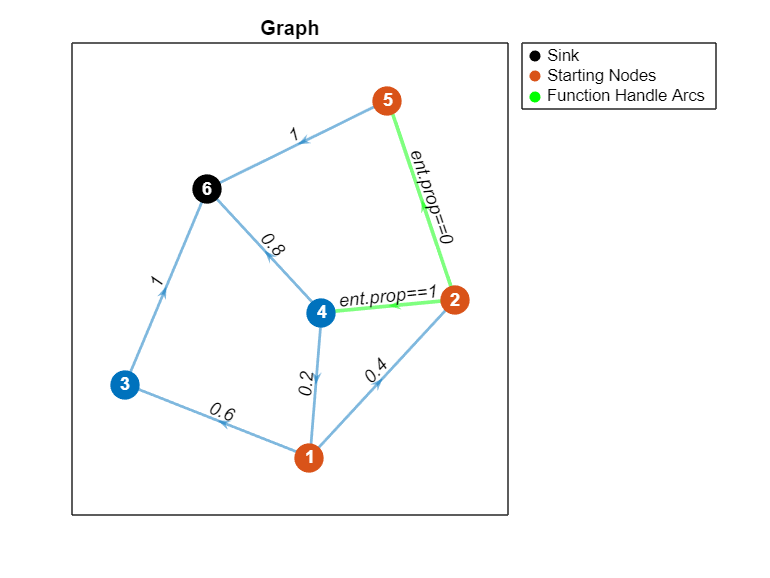

% Costruzione dell'oggetto Network
net = Network(matrice_adiacenza, distr_InterArrivi, distr_TempiServizio, policy);
stampa_grafo(net)

La simulazione vera e propria viene inizializzata passando al costruttore della classe `Simulation` l'oggetto `Network` precedentemente definito, insieme a una lista di attributi con i relativi valori possibili per le entità. In questo modo, a ogni entità generata durante la simulazione viene assegnato casualmente uno dei valori specificati, rendendo possibile la personalizzazione del comportamento in base alle sue caratteristiche.

% Inizializzo una simulazione
attributi_entita = [];
attributi_entita.prop =  {0, 1};
sim = Simulation(net, attributi_entita);


A questo punto, il sistema è pronto per l’esecuzione della simulazione, che avviene chiamando il metodo `run()` della classe `Simulation`. Questo metodo richiede in input l’orizzonte temporale della simulazione e un parametro booleano che controlla la quantità di output stampato durante l’esecuzione.

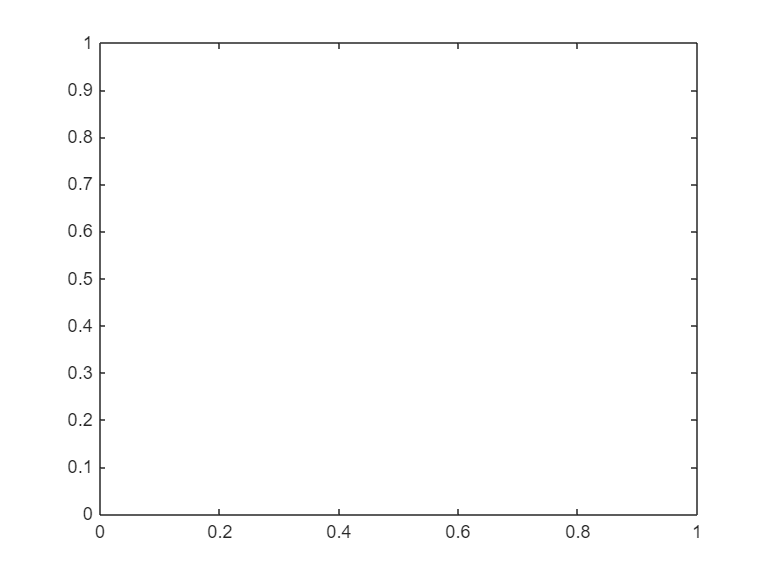


 ********************************* 
 INIZIO SIMULAZIONE ...  
 CLOCK = 1.73
 L'entità 1 è stata generata al nodo 1. 
 L'entità 1 ha iniziato il servizio presso il server 1 del nodo 1. 
 
 CLOCK = 13.05
 L'entità 2 è stata generata al nodo 1. 
 L'entità 2 ha iniziato il servizio presso il server 2 del nodo 1. 
 
 CLOCK = 18.78
 L'entità 3 è stata generata al nodo 2. 
 L'entità 3 ha iniziato il servizio presso il server 1 del nodo 2. 
 
 CLOCK = 18.92
 L'entità 3 ha terminato il servizio al nodo 2 ed è passata al nodo 4. 
 L'entità 3 ha iniziato il servizio presso il server 1 del nodo 4. 
 
 CLOCK = 19.68
 L'entità 3 ha terminato il servizio al nodo 4 ed è passata al nodo 1. 
 
 CLOCK = 20.00
 L'entità 4 è stata generata al nodo 5. 
 L'entità 4 ha iniziato il servizio presso il server 1 del nodo 5. 
 
 CLOCK = 25.72
 L'entità 5 è stata generata al nodo 1. 
 
 CLOCK = 27.43
 L'entità 4 ha terminato il servizio al nodo 5 ed è passata al nodo 6. 
 
 CLOCK = 30.72
 L'entità 1 ha terminato i

Error using AverageEntityNetworkTime/return_stat (line 24)
Nessun entità ha lasciato la rete

Error in Simulation/run (line 88)
                avg_ent_net_time = self.statistics{1}.retu

TIMEORIZON = 100;
stats = sim.run(TIMEORIZON,true);

Il metodo `run()` restituisce un *cell array* che contiene tutte le statistiche raccolte durante la simulazione, utili per l’analisi delle prestazioni del sistema simulato.

stats